**Project - Equations of motion matlab script**

**Initialize**

%syms mc mp x dx l th dth g F Fcart Fpend ddx ddth s Fdist b
mc=0.9+0.1; 
mp=0.08887;
l= 0.36022;
g = 9.82;
b = 1;

**Without Disturbance linear**

E = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fpend];
S = solve(E,ddx,ddth);
S.ddx;
S.ddth;

**With Disturbance linaer**

E1 = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fdist-Fpend];
S1 = solve(E1,ddx,ddth);
S1.ddx;
S1.ddth;

**Nonlinear**

E2 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-Fcart, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -Fpend];
S2 = solve(E2, ddx, ddth);
S2.ddx;
S2.ddth;

**Fpend and Fcart are b * x/th**

E3 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-b*dx, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -b*dth];
S3 = solve(E3, ddx, ddth);
S3.ddx;
S3.ddth;

**State Space Model**

C1 = [0 0 1 0;
      1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
A = [0 0 1 0;
     0 0 0 1;
     0 (-g*mp)/(mc+2*mp) 0 0;
     0 -(g*(mp+mc))/(l*(mc+2*mp)) 0 0];
  
B = [0 0;
     0 0;
     1/(mc+2*mp) 1/(l*(mc+2*mp));
     -1/(l*(mc+2*mp)) -(mc+mp)/(l^2*mp*(mc+2*mp))];

u = [F-Fcart; -Fpend];
 
system = ss(A,B,C,0);


**Observability and Controlability**

observability = obsv(system);
rank(observability); % Full rank

controlability = ctrb(system);
rank(controlability); % Full rank

**Transfer functions**

[Gnum,Gden] = ss2tf(A,B,C,[0 0; 0 0], 1);
SS2TF1 = Gnum(1,:);
SS2TF2 = Gnum(2,:);
 
G1 =tf(SS2TF1, Gden)

G1 =
 
  0.8491 s^3 + 23.15 s
  --------------------
     s^4 + 25.2 s^2
 
Continuous-time transfer function.



G2 =tf(SS2TF2, Gden)

G2 =
 
  0.8491 s^2 + 23.15
  ------------------
    s^4 + 25.2 s^2
 
Continuous-time transfer function.



**PID**

Kp = 5;
Ti = 0.1;
Td = 1;

Ks = Kp * (1 + 1 / (Ti * s) + Td * s)

Ks =
 
  0.5 s^2 + 0.5 s + 5
  -------------------
         0.1 s
 
Continuous-time transfer function.



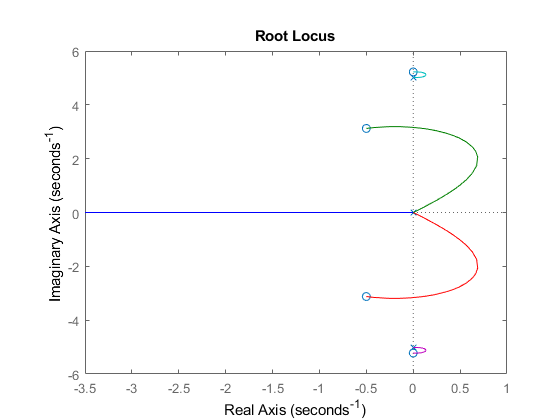

rlocus(Ks * G2)

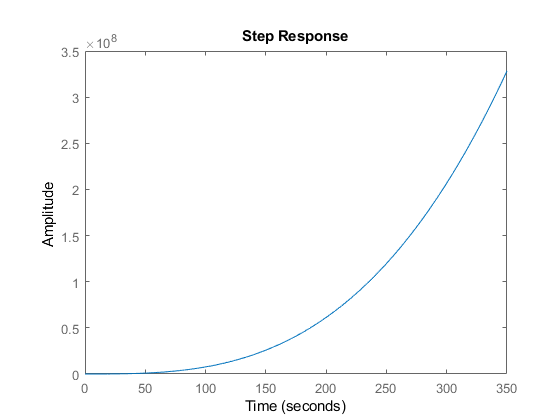

step(Ks*G2)


% pid(Kp,Ti,Td)






% rlocus(G1);
% rlocus(G2);
% It uses rational numbers instead of decimals.
%  G = C*inv((s-A))*B*u
%  simplify(G);